#     Qc

clear; clc; close all;
craneA = [140 140 112 90 32 154 359 207 61 39 40];
craneB = [69 14 38 94 46 36 84 106 269 445 42 108 244 92 148 303 24 328 207 260 132 56];
craneC = [39 135 57 31 190 90 293 151 26 77 82 156 328 92 138 47 45];

## 情况1：Qb中组间差异不显著(平均运行时间是否 > 120 小时?)

crane_all = [craneA(:); craneB(:); craneC(:)];
n = numel(crane_all);
mu0 = 120;
alpha = 0.05;
xbar = mean(crane_all);
s = std(crane_all, 0);
med = median(crane_all);
mx = max(crane_all);
mn = min(crane_all);
iqrVal = iqr(crane_all);

fprintf('n = %d, mean = %.2f, median = %.2f, std = %.2f, IQR = %.2f, min = %.2f, max = %.2f\n\n', ...
    n, xbar, med, s, iqrVal, mn, mx);

n = 50, mean = 129.92, median = 93.00, std = 102.48, IQR = 110.00, min = 14.00, max = 445.00



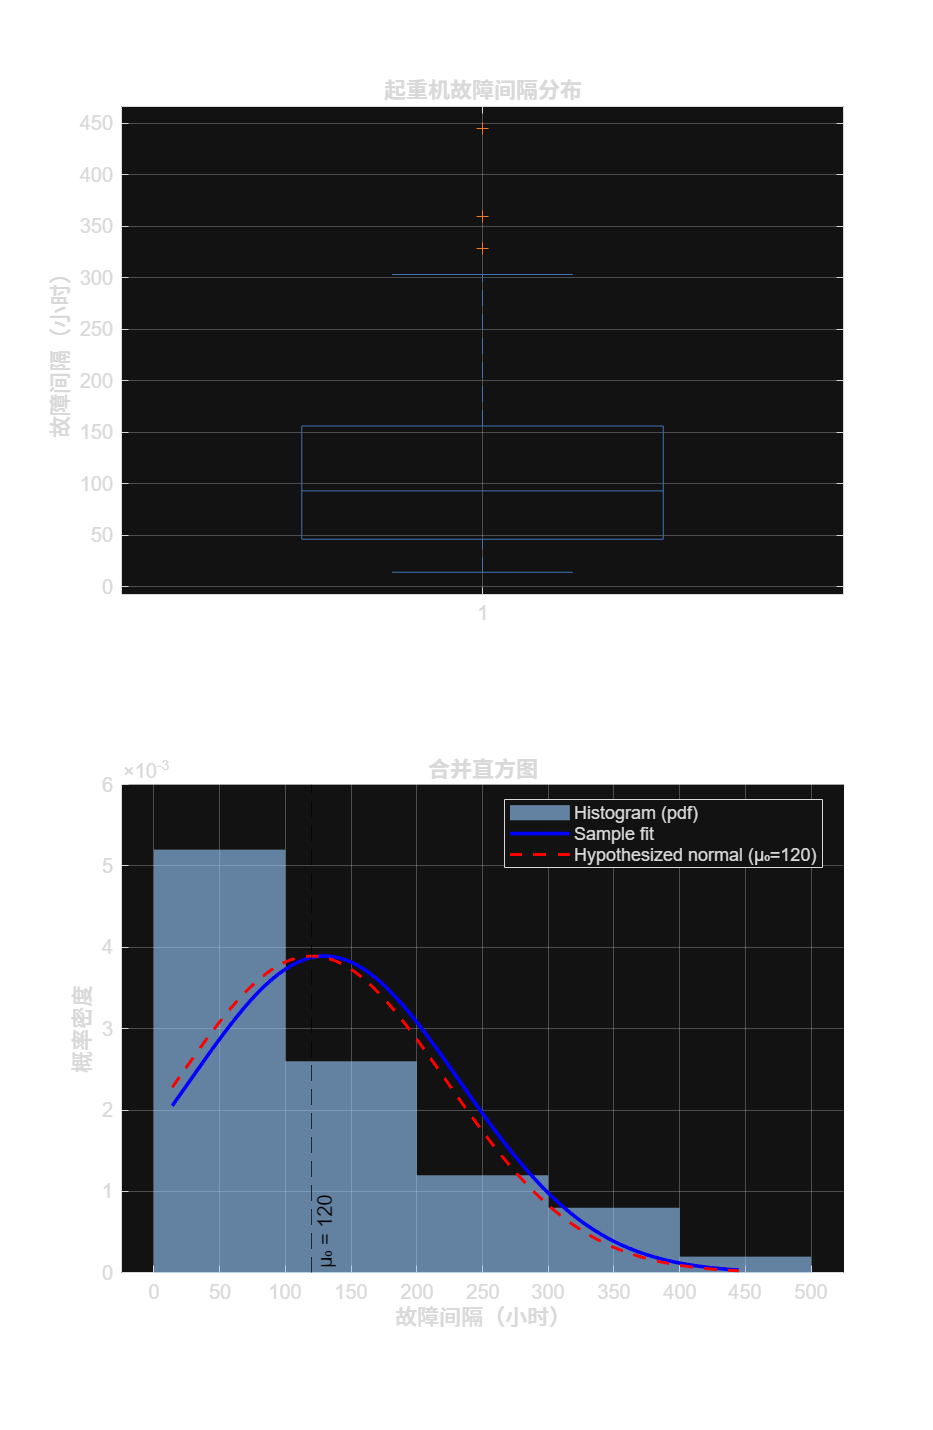

%% 可视化检查

figure('Color','w','Position',[100 100 980 1500]);
% 箱线图
subplot(2,1,1);
boxplot(crane_all, 'Colors',[0.25 0.45 0.7], 'Widths',0.5);
ylabel('故障间隔（小时）'); title('起重机故障间隔分布'); 
grid on;
%% 直方图
subplot(2,1,2); hold on;
histogram(crane_all, 'Normalization','pdf', ...
    'FaceColor',[0.6 0.8 1], 'EdgeColor','none');
% 样本拟合曲线（基于样本均值/方差）
xx_0 = linspace(min(crane_all), max(crane_all), 300);
plot(xx_0, normpdf(xx_0, mean(crane_all), std(crane_all,0)), ...
    'b-', 'LineWidth', 1.8);
% 假设正态曲线（基于 μ₀ / 样本方差）
plot(xx_0, normpdf(xx_0, mu0, std(crane_all,0)), ...
    'r--', 'LineWidth', 1.5);
% 基准线（μ₀ = 120）
xline(mu0, '--k', 'μ₀ = 120', 'LabelVerticalAlignment','bottom');

 xlabel('故障间隔（小时）'); ylabel('概率密度');
title('合并直方图'); 
legend('Histogram (pdf)', 'Sample fit', 'Hypothesized normal (μ₀=120)', 'Location','best');
grid on; hold off;

## One-Sample t-Test

SE   = s / sqrt(n);
df   = n - 1; 
t_stat = (xbar - mu0) / SE;

% 单尾右尾 p 值 与 临界值
if exist('tcdf','file')==2
    p_right     = 1 - tcdf(t_stat, df);
    tcrit_right = tinv(1 - alpha, df);
else
     p_right     = 1 - normcdf(t_stat, 0, 1);
     tcrit_right = norminv(1 - alpha, 0, 1);
end


% 单侧(1-α)下界置信限(上界为正无穷）
LB_one_sided = xbar - tcrit_right * SE;
% 结论
if p_right < alpha
    decision = "Reject H0 (evidence mean > 120h)";
else
    decision = "Fail to reject H0 (no significant evidence mean > 120h)";
end


## t-检验结果

fprintf('\n--- One-Sample t-Test (one-tailed: H1: μ > %.0f h) ---\n', mu0);


--- One-Sample t-Test (one-tailed: H1: μ > 120 h) ---


fprintf('t-statistic = %.4f | df = %d\n', t_stat, df);

t-statistic = 0.6845 | df = 49


fprintf('One-tailed p-value = %.4f\n', p_right);

One-tailed p-value = 0.2485


fprintf('t-critical (one-tail, α=%.2f) = %.3f\n', alpha, tcrit_right);

t-critical (one-tail, α=0.05) = 1.677


fprintf('95%% one-sided lower bound for μ: [%.2f, +Inf) h\n', LB_one_sided);

95% one-sided lower bound for μ: [105.62, +Inf) h


fprintf('Decision: %s\n', decision);

Decision: Fail to reject H0 (no significant evidence mean > 120h)



% 总结表
ResultsTable = table(n, xbar, s, SE, df, t_stat, tcrit_right, p_right, ...
                     LB_one_sided, string(decision), ...
    'VariableNames', {'n','Mean','StdDev','StdError','df','t_stat','tcrit_right', ...
                      'p_value','CI_Lower','Decision'});
disp(ResultsTable);

    n      Mean     StdDev    StdError    df    t_stat     tcrit_right    p_value    CI_Lower                            Decision                         
    __    ______    ______    ________    __    _______    ___________    _______    ________    _________________________________________________________

    50    129.92    102.48     14.493     49    0.68446      1.6766       0.24846     105.62     "Fail to reject H0 (no significant evidence mean > 120h)"



## 可视化t分布

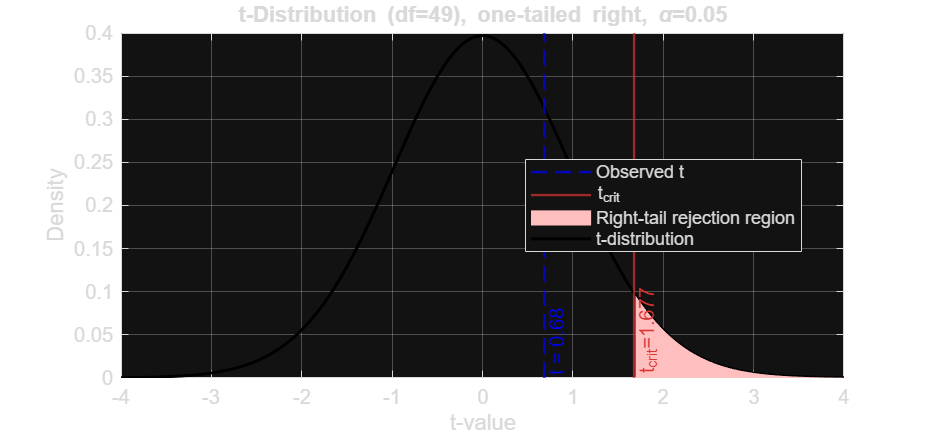

x = linspace(-4,4,400);
if exist('tpdf','file')==2
    pdf_t = tpdf(x, df);
else
    pdf_t = normpdf(x, 0, 1);
end

figure('Color','w','Position',[100 100 900 420]);
plot(x, pdf_t, 'k', 'LineWidth', 1.5); hold on; grid on;

% 单尾右尾拒绝域
idxR = x > tcrit_right;
area(x(idxR), pdf_t(idxR), 'FaceColor',[1 0.75 0.75], 'EdgeColor','none');

% 临界线
xline(tcrit_right, '-', sprintf('t_{crit}=%.3f', tcrit_right), ...
    'LineWidth',1.2, 'Color',[0.85 0.2 0.2], 'LabelVerticalAlignment','bottom');

% t统计量
xline(t_stat, '--b', sprintf('t = %.2f', t_stat), ...
    'LineWidth',1.3, 'LabelVerticalAlignment','bottom');

xlabel('t-value'); ylabel('Density');
title(sprintf('t-Distribution (df=%d), one-tailed right, \\alpha=%.2f', df, alpha));
legend('t-distribution','Right-tail rejection region','t_{crit}','Observed t', ...
       'Location','best');
hold off;

## 结论

fprintf('\n--- Interpretation (One-tailed: H1: μ > %.0f h) ---\n', mu0);


--- Interpretation (One-tailed: H1: μ > 120 h) ---


fprintf('x̄ = %.2f h (n = %d), t = %.4f, p(one-tail) = %.4f, df = %d\n', xbar, n, t_stat, p_right, df);

x̄ = 129.92 h (n = 50), t = 0.6845, p(one-tail) = 0.2485, df = 49


fprintf('t-critical (one-tail, α=%.2f) = %.3f\n', alpha, tcrit_right);

t-critical (one-tail, α=0.05) = 1.677


fprintf('95%% two-sided CI for μ = [%.4f, +∞） \n', tcrit_right);

95% two-sided CI for μ = [1.6766, +∞） 


if p_right < alpha
    fprintf('→ Reject H0: mean runtime is significantly GREATER than %.0f h.\n', mu0);
else
    fprintf('→ Fail to reject H0: no significant evidence that mean runtime > %.0f h.\n', mu0);
end

→ Fail to reject H0: no significant evidence that mean runtime > 120 h.


## 情况二 Qb中组间差异显著(每台起重机的平均运行时间是否 > 120 小时?)

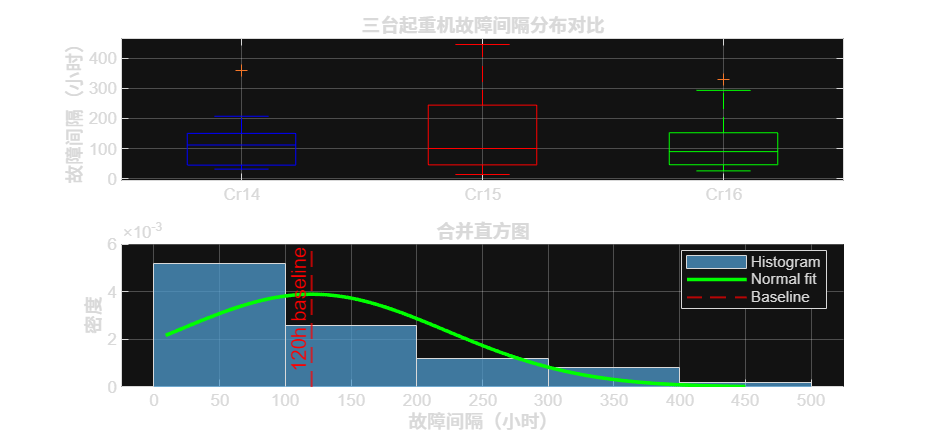

group = [...
    repmat({'Cr14'}, numel(craneA), 1);
    repmat({'Cr15'}, numel(craneB), 1);
    repmat({'Cr16'}, numel(craneC), 1) ];
% (a) 分组三箱线图，便于识别差异与离群点
subplot(2,1,1);
boxplot(crane_all, group, ...
        'Colors', ['b','r', 'g']);
title('三台起重机故障间隔分布对比'); ylabel('故障间隔（小时）');
grid on;

% (b) 合并样本直方图 + 正态拟合
subplot(2,1,2); hold on;
histogram(crane_all, 'Normalization','pdf', 'FaceColor',[0.3 0.6 0.8], 'FaceAlpha',0.75);
xx = linspace(mn-5, mx+5, 300);
plot(xx, normpdf(xx, mu0, s), 'g-', 'LineWidth',1.8);
xline(mu0, '--r', '120h baseline', ...
      'LabelHorizontalAlignment','left', 'LineWidth', 1);
title('合并直方图');
xlabel('故障间隔（小时）'); ylabel('密度');
legend({'Histogram','Normal fit','Baseline'}, 'Location','best');
grid on; hold off;